# DSP Lab - Homework8

#### Mahdi Mahjouri Namin 40023125

#### Nima Nourizadeh 40023086

clc;
clear;
close all;

## Section 3-3 a


fs = 1e3;
t = 0:1 / fs:1;
A = 2;
x = A * cos(2 * pi * 50 * t);
disp("Calculated value of MS of X:");

Calculated value of MS of X:



ms_val_x = mean(x .^ 2);
disp(ms_val_x);

    2.0020



disp(0.5*A^2)

     2



mean(abs(x))

ans = 1.2635

disp(rms(x) ^ 2);

    2.0020



mean_abs_x = mean(abs(x))

mean_abs_x = 1.2635

disp('Mean of x');

Mean of x


disp(2 * A / pi);

    1.2732



## Section 3-3 b

**Compressor**

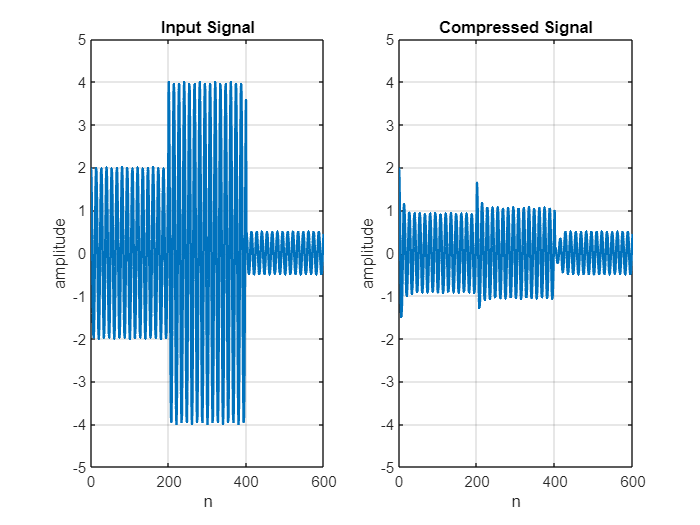


w0 = pi * 0.15;
n = [0:199; 200:399; 400:599];
A = [2 4 0.5];
x = cos(w0 * n) .* A';
x = x';
x = x(1:end);
n = n';
n = n(1:end);


lambda = 0.9;
c0 = 0.5;
rho = 0.2;
b = 1 - lambda;
a = [1 -lambda];
cn = filter(b, a, abs(x));

gn = ones(1, length(cn));
gn(cn >= c0) = (cn(cn >= c0) / c0) .^ (rho - 1);
yn = gn .* x;


figure("Name", 'Input Signal vs Compressed Signal');
subplot(1, 2, 1);
plot(n, x, 'LineWidth', 1.5);
title('Input Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;
subplot(1, 2, 2);
plot(n, yn, 'LineWidth', 1.5);
title('Compressed Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;

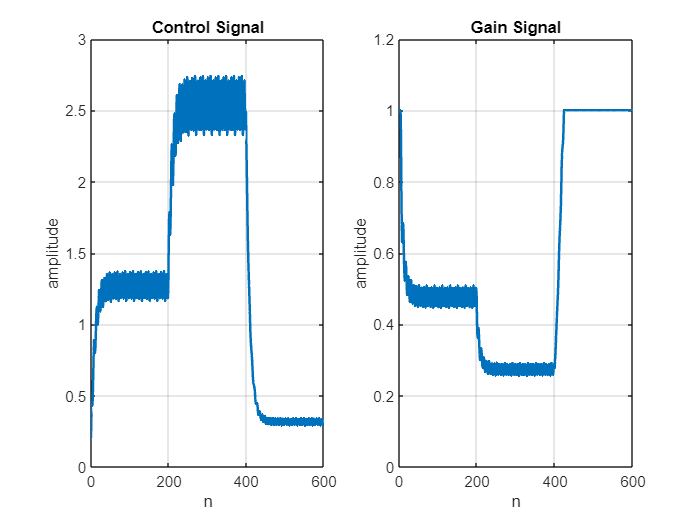

figure('Name', 'Contol Signal vs Gain Signal');
subplot(1, 2, 1);
plot(n, cn, 'LineWidth', 1.5);
title('Control Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 3]);
grid on;
subplot(1, 2, 2);
plot(n, gn, 'LineWidth', 1.5);
title('Gain Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 1.2]);
grid on;

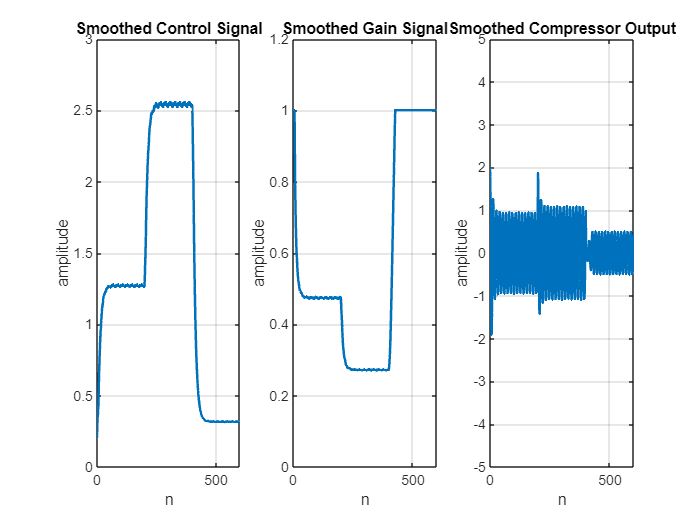



L = 7;
cn_smoothed = movmean(cn, [L - 1 0]);
gn_smoothed = ones(1, length(cn_smoothed));
gn_smoothed(cn_smoothed >= c0) = (cn_smoothed(cn_smoothed >= c0) / c0) .^ (rho - 1);
yn_smoothed = gn_smoothed .* x;
figure('Name', 'Smoothed Contol Signal vs Smoothed Gain Signal');
subplot(1, 3, 1);
plot(n, cn_smoothed, 'LineWidth', 1.5);
title('Smoothed Control Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 3]);
grid on;
subplot(1, 3, 2);
plot(n, gn_smoothed, 'LineWidth', 1.5);
title('Smoothed Gain Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 1.2]);
grid on;

subplot(1, 3, 3);
plot(n, yn_smoothed, 'LineWidth', 1.5);
title('Smoothed Compressor Output');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;

### limiter

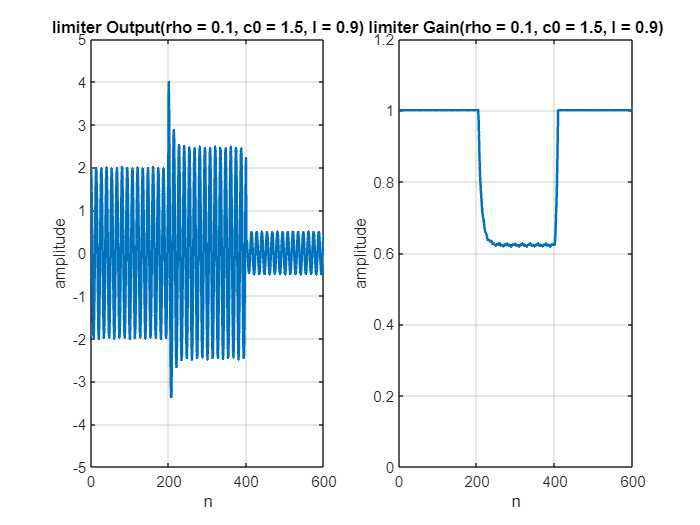

lambda = 0.9;
c0 = 1.5;
rho = 0.1;

gn_limiter = ones(1, length(cn_smoothed));
gn_limiter(cn_smoothed >= c0) = (cn_smoothed(cn_smoothed >= c0) / c0) .^ (rho - 1);
yn_limiter = gn_limiter .* x;

figure;
subplot(1, 2, 1);
plot(n, yn_limiter, 'LineWidth', 1.5);
title('limiter Output(rho = 0.1, c0 = 1.5, l = 0.9)'); % l = lambda
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;

subplot(1, 2, 2);
plot(n, gn_limiter, 'LineWidth', 1.5);
title('limiter Gain(rho = 0.1, c0 = 1.5, l = 0.9)'); % l = lambda
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 1.2]);
grid on;

### Expander

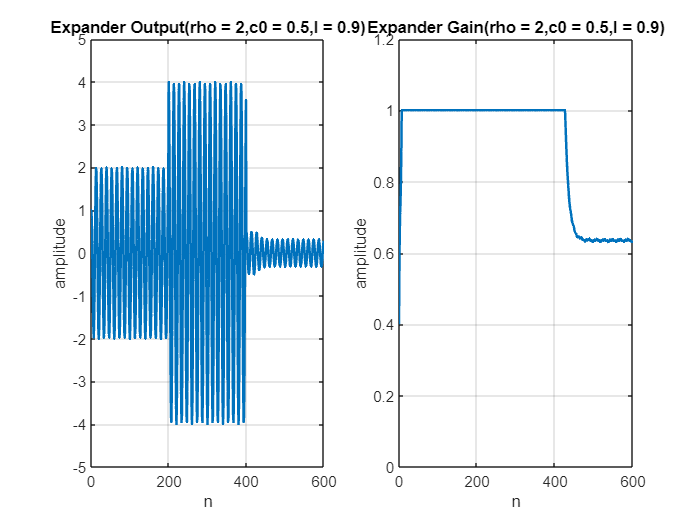


lambda = 0.9;
c0 = 0.5;
rho = 2;

gn_expander = ones(1, length(cn_smoothed));
gn_expander(cn_smoothed < c0) = (cn_smoothed(cn_smoothed < c0) / c0) .^ (rho - 1);
yn_expander = gn_expander .* x;

figure;
subplot(1, 2, 1);
plot(n, yn_expander, 'LineWidth', 1.5);
title('Expander Output(rho = 2,c0 = 0.5,l = 0.9)');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;

subplot(1, 2, 2);
plot(n, gn_expander, 'LineWidth', 1.5);
title('Expander Gain(rho = 2,c0 = 0.5,l = 0.9)');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 1.2]);
grid on;

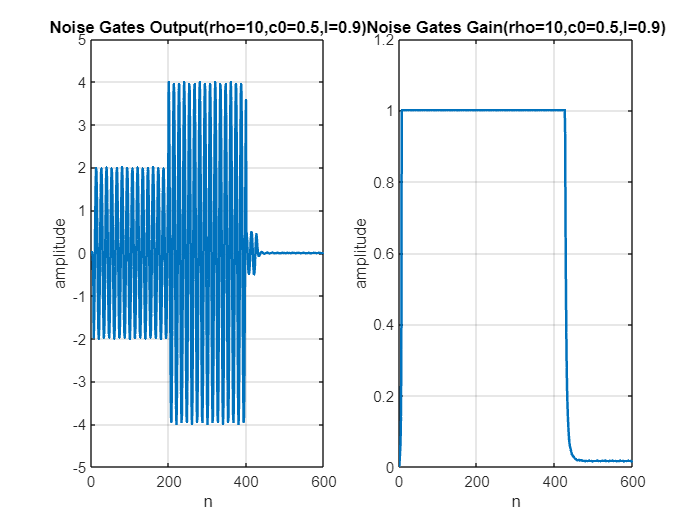

lambda = 0.9;
c0 = 0.5;
rho = 10;

gn_noise = ones(1, length(cn_smoothed));
gn_noise(cn_smoothed < c0) = (cn_smoothed(cn_smoothed < c0) / c0) .^ (rho - 1);
yn_noise = gn_noise .* x;

figure;
subplot(1, 2, 1);
plot(n, yn_noise, 'LineWidth', 1.5);
title('Noise Gates Output(rho=10,c0=0.5,l=0.9)');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;

subplot(1, 2, 2);
plot(n, gn_noise, 'LineWidth', 1.5);
title('Noise Gates Gain(rho=10,c0=0.5,l=0.9)');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 1.2]);
grid on;

## Section 3-3 c

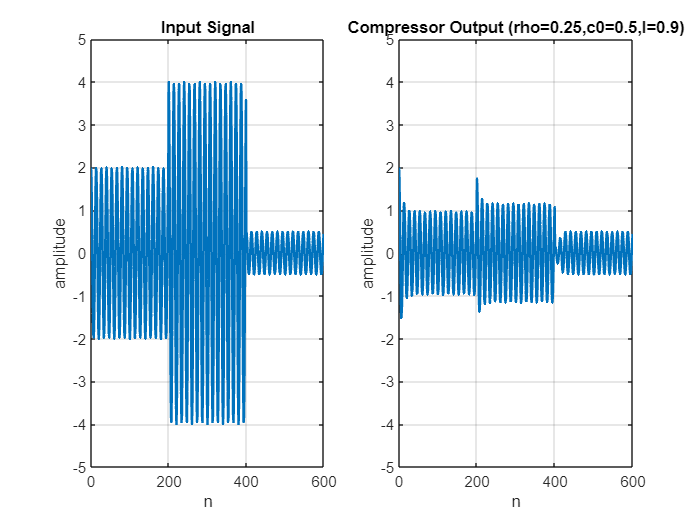

c0 = 0.5;
rho = 0.25; 

gn_1 = ones(1, length(cn));
gn_1(cn >= c0) = (cn(cn >= c0) / c0) .^ (rho - 1);
yn_1 = gn_1 .* x;

figure("Name", 'Input Signal vs Compressed Signal');
subplot(1, 2, 1);
plot(n, x, 'LineWidth', 1.5);
title('Input Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;
subplot(1, 2, 2);
plot(n, yn_1, 'LineWidth', 1.5);
title('Compressor Output (rho=0.25,c0=0.5,l=0.9)');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;

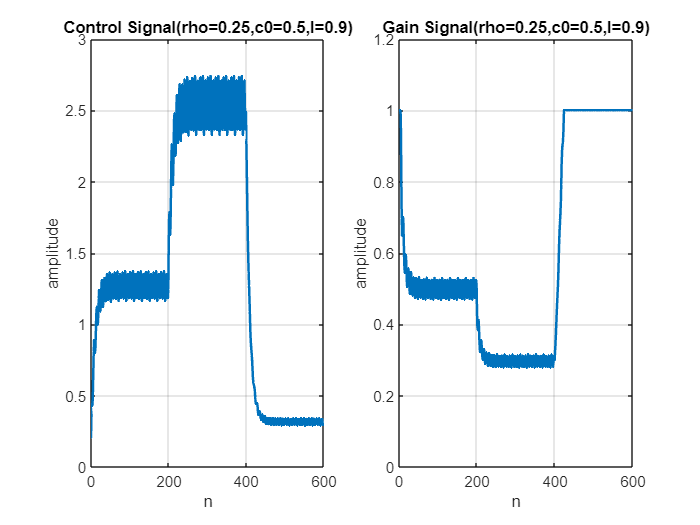

figure('Name', 'Contol Signal vs Gain Signal'); % Control and Gain signal with new parameters
subplot(1, 2, 1);
plot(n, cn, 'LineWidth', 1.5);
title('Control Signal(rho=0.25,c0=0.5,l=0.9)');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 3]);
grid on;
subplot(1, 2, 2);
plot(n, gn_1, 'LineWidth', 1.5);
title('Gain Signal(rho=0.25,c0=0.5,l=0.9)');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 1.2]);
grid on;

## Section 3-3 d

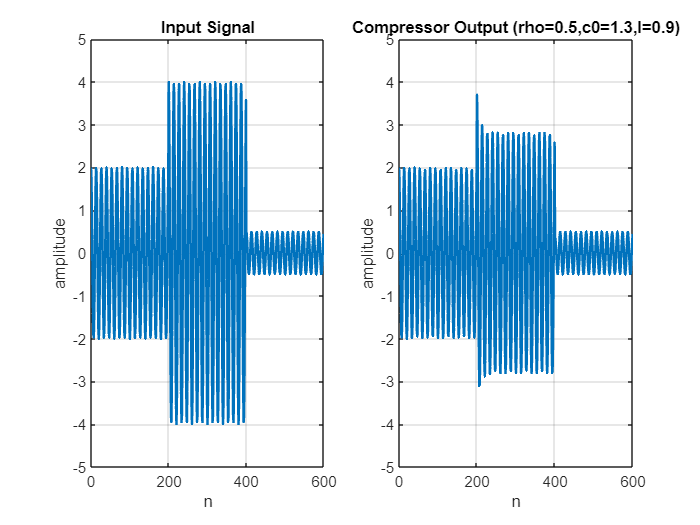

c0 = 1.3;
rho = 0.5; 

gn_2 = ones(1, length(cn));
gn_2(cn >= c0) = (cn(cn >= c0) / c0) .^ (rho - 1);
yn_2 = gn_2 .* x;

figure("Name", 'Input Signal vs Compressed Signal');
subplot(1, 2, 1);
plot(n, x, 'LineWidth', 1.5);
title('Input Signal');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;
subplot(1, 2, 2);
plot(n, yn_2, 'LineWidth', 1.5);
title('Compressor Output (rho=0.5,c0=1.3,l=0.9)');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([-5 5]);
grid on;

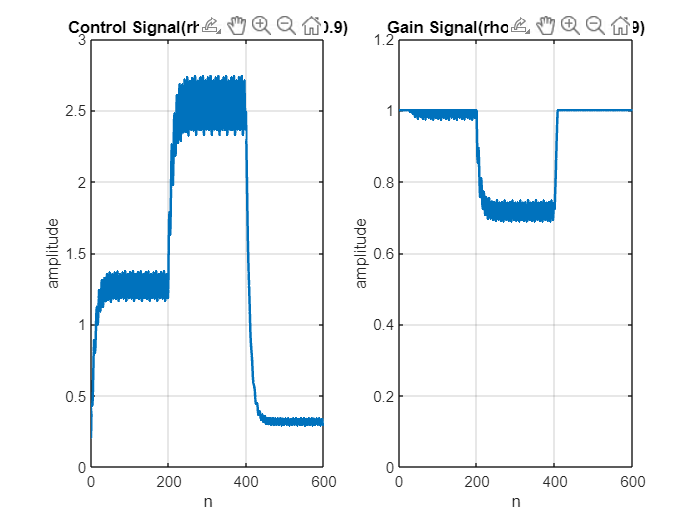

figure('Name', 'Contol Signal vs Gain Signal'); % Control and Gain signal with new parameters
subplot(1, 2, 1);
plot(n, cn, 'LineWidth', 1.5);
title('Control Signal(rho=0.5,c0=1.3,l=0.9)');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 3]);
grid on;
subplot(1, 2, 2);
plot(n, gn_2, 'LineWidth', 1.5);
title('Gain Signal(rho=0.5,c0=1.3,l=0.9)');
xlabel('n');
ylabel('amplitude');
xlim([0 600]);
ylim([0 1.2]);
grid on;

            With the parameters set to:

            **c₀ = 1.3**, **ρ = 0.5**, and **λ = 0.9**,

            only the middle part of the signal is compressed.

            This happens because the gain function is defined as:

              **Gₙ = (cₙ / c₀)^(ρ−1)**  if **cₙ ≥ c₀**,

              **Gₙ = 1**  otherwise.

            Here, **cₙ** is the smoothed control signal based on the input amplitude.

            For the three signal segments with amplitudes A = [2, 4, 0.5],

            the effective values of |xₙ| are approximately:

              [1.27, 2.55, 0.32]

            Only the last segment (A = 4) produces a control signal above the threshold c₀ = 1.3,

            which activates the compressor and reduces the gain (Gₙ < 1).

            The first two segments stay below the threshold, resulting in Gₙ = 1, so they pass uncompressed.

            Therefore, compression is applied only to the high-amplitude (middle) segment of the signal.